# Daniel Chang 

# Lab 4 M150 

warning('off', 'all')

## Exercise 1A: **Test the hypothesis that reductions in the zone of detection decrease the number of prey eaten by a squared factor. For example, try predator.r=1 and then while keeping all other parameters the same set predator.r=0.5 and see if the number of prey eaten drops by 1/4.  **

The hypothesis is partially supported. Havling the detection radius (r of 1 to 0.5) reduced consumption by about 3.72x which is close to but not exactly the predicted 4x (r^2 scaling). The small reduction makes sense since the theory assumes that predators always finds a uniformly stocked environment. However, in the simulation, the predator locally gets prey around itself. At larger r values, this effect becomes stronger. That being said, the gain from a larger zone is slightly less than the geometric prediction. 

My results from the code below: 

`r = 1.25 : final eaten = 31.15 +/- 3.60`

`r = 1.00 : final eaten = 21.20 +/- 4.82`

`r = 0.50 : final eaten = 5.70 +/- 1.92`

`Ratio (r=1.0)/(r=0.5): measured = 3.72, predicted r^2 = 4.00`

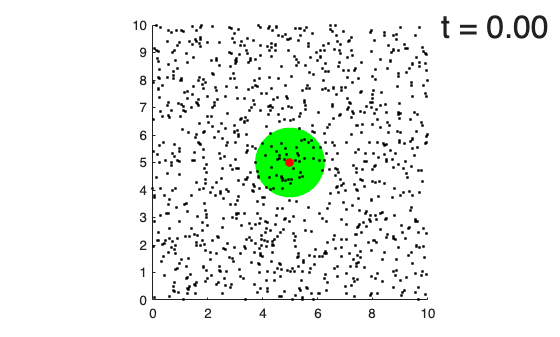

r = 1.25 : final eaten = 31.15 +/- 3.60
r = 1.00 : final eaten = 21.20 +/- 4.82
r = 0.50 : final eaten = 5.70 +/- 1.92


clear; clc; 
% ensemble size for averaging
n_ens     = 20;              
% radii to test
r_values  = [1.25, 1.0, 0.5]; 
% array to hold the final r values 
finals    = zeros(size(r_values));

figure; hold on;
colors = lines(length(r_values));

% going through the r values
for i = 1:length(r_values)
    [info, predator, prey] = lab4_default_params();
    predator.r = r_values(i);
    [t, m, s, ~] = lab4_ensemble(info, predator, prey, n_ens);
    plot(t, m, 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', sprintf('r = %.2f  (final = %.1f \\pm %.1f)', ...
                                r_values(i), m(end), s(end)));
    fill([t fliplr(t)], [m+s fliplr(m-s)], colors(i,:), ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    % appending final value to array 
    finals(i) = m(end);
    % print statement corresponding to each r value being tested
    fprintf('r = %.2f : final eaten = %.2f +/- %.2f\n', r_values(i), m(end), s(end));
end

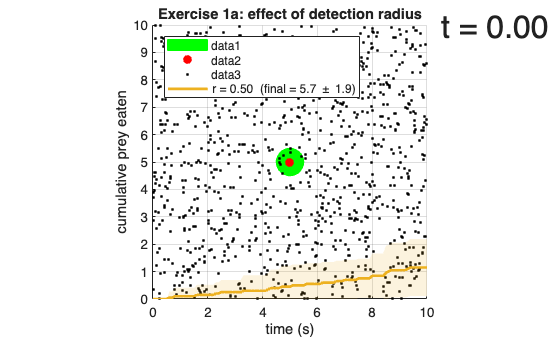

xlabel('time (s)'); ylabel('cumulative prey eaten');
title('Exercise 1a: effect of detection radius');
legend('Location', 'northwest'); grid on;

% Check the squared-scaling hypothesis
% r=1.0 / r=0.5
ratio_meas = finals(2) / finals(3);       
% should be 4
ratio_pred = (r_values(2) / r_values(3))^2;    
fprintf('\nRatio (r=1.0)/(r=0.5): measured = %.2f, predicted r^2 = %.2f\n', ...
        ratio_meas, ratio_pred);


Ratio (r=1.0)/(r=0.5): measured = 3.72, predicted r^2 = 4.00


## Exercise 1B: **Evaluate how changes in velocity modify the scaling relationship.**

Based on my results, velocity seems to have a weak, saturating positive effect. From a 20x increase in velocity (0.05 -> 1.00), total consumption increases by about 30.1% (38.60 -> 37.45). This may be because the leading-order theory (pi*r^2fk*N*t_f) does not contain v. Velocity is affected through the swept-area correction term 2rvT_s and is small when v is small relative to r. Once the predator is moving fast enough to catch prey, going faster would lead to diminishing returns explaining why its a weak, saturating positive effect.  

My results from the code below:

`v = 0.05 : final eaten = 28.60 +/- 6.16`

`v = 0.10 : final eaten = 31.90 +/- 5.33`

`v = 0.20 : final eaten = 33.45 +/- 4.93`

`v = 0.50 : final eaten = 38.20 +/- 5.66`

`v = 1.00 : final eaten = 37.45 +/- 7.60`

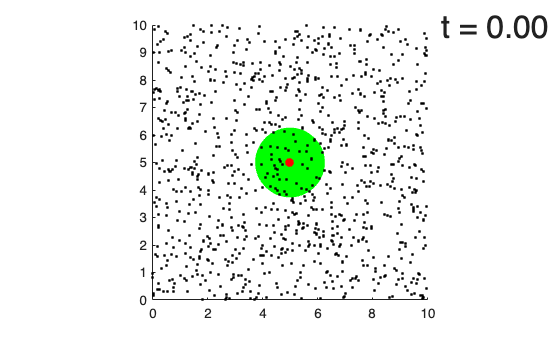

v = 0.05 : final eaten = 28.60 +/- 6.16
v = 0.10 : final eaten = 31.90 +/- 5.33
v = 0.20 : final eaten = 33.45 +/- 4.93
v = 0.50 : final eaten = 38.20 +/- 5.66
v = 1.00 : final eaten = 37.45 +/- 7.60


clear; clc; 
n_ens    = 20;
% velocity values to test 
v_values = [0.05, 0.1, 0.2, 0.5, 1.0];
% array called finals filled with zeroes that is length of the # of
% velocity values to store the final values 
finals   = zeros(size(v_values));

figure; hold on;
colors = lines(length(v_values));

% going through each velocity value
for i = 1:length(v_values)
    [info, predator, prey] = lab4_default_params();
    predator.vel = v_values(i);
    [t, m, s, ~] = lab4_ensemble(info, predator, prey, n_ens);
    plot(t, m, 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', sprintf('v = %.2f  (final = %.1f \\pm %.1f)', ...
                                v_values(i), m(end), s(end)));
    fill([t fliplr(t)], [m+s fliplr(m-s)], colors(i,:), ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    finals(i) = m(end);
    fprintf('v = %.2f : final eaten = %.2f +/- %.2f\n', v_values(i), m(end), s(end));
end

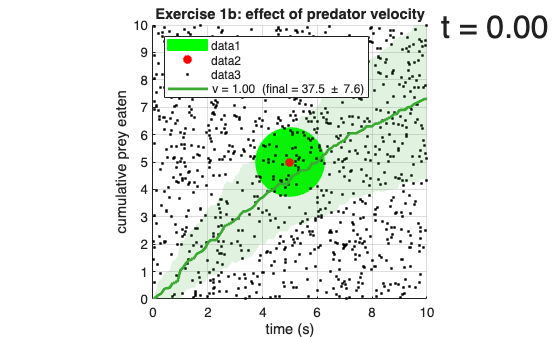

xlabel('time (s)'); ylabel('cumulative prey eaten');
title('Exercise 1b: effect of predator velocity');
legend('Location', 'northwest'); grid on;

## Exercise 1C: Modify the diffusion coefficient of prey, does it modify the consumption rate of predators?

Based on my results, prey diffusion had minimal effect on predator consumption across the tested range. From D = 0 to D = 0.05, values ranged from 27.40 to 35.80 but all overlap within their standard deviations, showing no clear trend. At D = 0.5 consumption reached 37.55, but then slightly decreased at D = 5.0 to 35.60, suggesting the effect plateaus at high diffusion.

This makes sense because the predator is the primary driver of encounters. Prey diffusion only matters when fast enough to replenish the detection zone between predator visits, requiring roughly D ~ r^2/(2Δt) ≈ 7.8. Since all tested values fall below this threshold, diffusion plays little role overall.

My results from the code below:

`D = 0.000 : final eaten = 27.40 +/- 5.00`

`D = 0.001 : final eaten = 31.50 +/- 5.25`

`D = 0.005 : final eaten = 28.30 +/- 6.07`

`D = 0.050 : final eaten = 35.80 +/- 4.37`

`D = 0.500 : final eaten = 37.55 +/- 8.49`

`D = 5.000 : final eaten = 35.60 +/- 4.12`

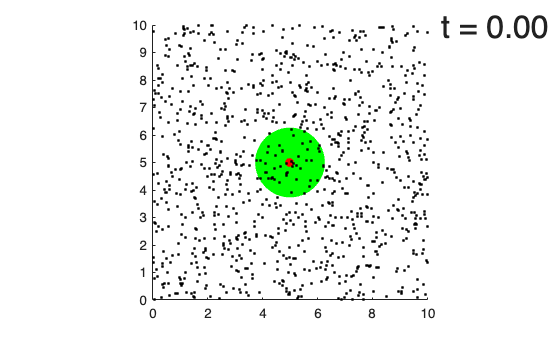

D = 0.000 : final eaten = 27.40 +/- 5.00
D = 0.001 : final eaten = 31.50 +/- 5.25
D = 0.005 : final eaten = 28.30 +/- 6.07
D = 0.050 : final eaten = 35.80 +/- 4.37
D = 0.500 : final eaten = 37.55 +/- 8.49
D = 5.000 : final eaten = 35.60 +/- 4.12


clear; clc;
n_ens    = 20;
D_values = [0, 0.001, 0.005, 0.05, 0.5, 5];   % cm^2/sec
finals   = zeros(size(D_values));

figure; hold on;
colors = lines(length(D_values));

for i = 1:length(D_values)
    [info, predator, prey] = lab4_default_params();
    prey.diffusion = D_values(i);
    [t, m, s, ~] = lab4_ensemble(info, predator, prey, n_ens);
    plot(t, m, 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', sprintf('D = %.3f  (final = %.1f \\pm %.1f)', ...
                                D_values(i), m(end), s(end)));
    fill([t fliplr(t)], [m+s fliplr(m-s)], colors(i,:), ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    finals(i) = m(end);
    fprintf('D = %.3f : final eaten = %.2f +/- %.2f\n', D_values(i), m(end), s(end));
end

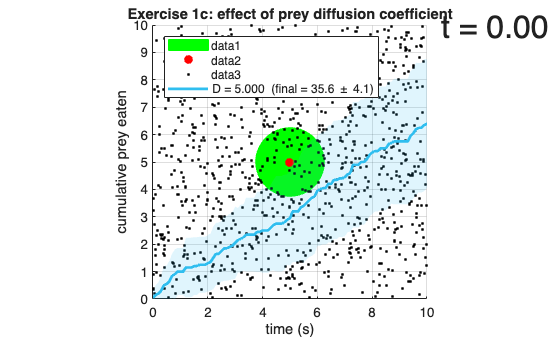

xlabel('time (s)'); ylabel('cumulative prey eaten');
title('Exercise 1c: effect of prey diffusion coefficient');
legend('Location', 'northwest'); grid on;

## Exercise 1D: Change the density of prey (don’t increase it beyond 50 or so) - how does prey consumption change.

Based on my results, prey consumption scales about linearly with density which is what bNP form predicts. Going from N = 1 to N = 50 increases consumption 52.9x which is pretty close to the expected 50x. The linearity check plot confirms this visually. The simulation points closely track the red dashed theoretical line sitting slightly below at higher densites due to the local depletion effect seen in exercise 1A. 

My results from the code below:

`N =  1 : final eaten = 2.90 +/- 1.65`

`N =  5 : final eaten = 14.30 +/- 3.96`

`N = 10 : final eaten = 29.45 +/- 5.66`

`N = 25 : final eaten = 77.80 +/- 9.65`

`N = 50 : final eaten = 153.30 +/- 10.93`

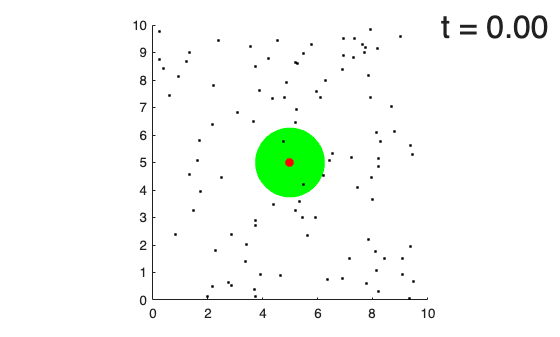

N =  1 : final eaten = 2.50 +/- 1.40
N =  5 : final eaten = 17.25 +/- 4.33
N = 10 : final eaten = 32.00 +/- 5.15
N = 25 : final eaten = 76.65 +/- 9.06
N = 50 : final eaten = 152.05 +/- 11.61


clear; clc;
n_ens    = 20;
N_values = [1, 5, 10, 25, 50];
finals   = zeros(size(N_values));
finals_std = zeros(size(N_values));

figure;
% Left panel: cumulative-eaten curves
subplot(1,2,1); hold on;
colors = lines(length(N_values));

for i = 1:length(N_values)
    [info, predator, prey] = lab4_default_params();
    info.prey_density = N_values(i);
    % rebuild prey from new density
    prey.num      = info.prey_density * info.maxX * info.maxY;
    prey.pos      = rand(prey.num, 2);
    prey.pos(:,1) = prey.pos(:,1) * info.maxX;
    prey.pos(:,2) = prey.pos(:,2) * info.maxY;

    [t, m, s, ~] = lab4_ensemble(info, predator, prey, n_ens);
    plot(t, m, 'LineWidth', 2, 'Color', colors(i,:), ...
         'DisplayName', sprintf('N = %d  (final = %.1f \\pm %.1f)', ...
                                N_values(i), m(end), s(end)));
    fill([t fliplr(t)], [m+s fliplr(m-s)], colors(i,:), ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    finals(i)     = m(end);
    finals_std(i) = s(end);
    fprintf('N = %2d : final eaten = %.2f +/- %.2f\n', N_values(i), m(end), s(end));
end

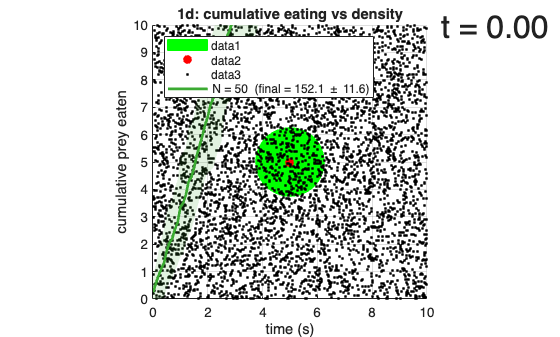

xlabel('time (s)'); ylabel('cumulative prey eaten');
title('1d: cumulative eating vs density');
legend('Location', 'northwest'); grid on;

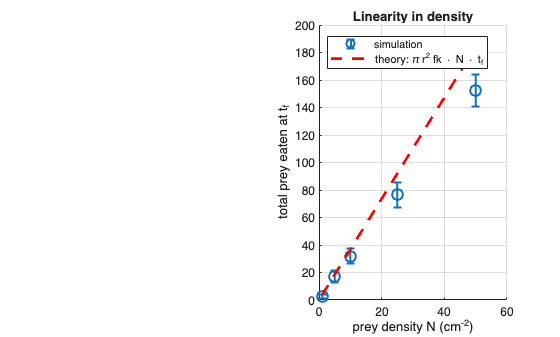

% Right panel: linearity check
subplot(1,2,2); hold on;
errorbar(N_values, finals, finals_std, 'o', 'MarkerSize', 8, 'LineWidth', 1.5, ...
         'DisplayName', 'simulation');
% theoretical: rate = pi r^2 f k * N, total over t_f = pi r^2 f k * N * t_f
b_pred = pi * 1.25^2 * 0.05 * 0.3;
plot(N_values, b_pred * N_values * 50, 'r--', 'LineWidth', 2, ...
     'DisplayName', 'theory: \pi r^2 fk \cdot N \cdot t_f');
xlabel('prey density N (cm^{-2})'); ylabel('total prey eaten at t_f');
title('Linearity in density'); legend('Location', 'northwest'); grid on;

## Exercise 1E: Set info.replenish prey=0. You should find that once prey are eaten they do not regenerate, how does that change the consumption rate over time?

Based on my results, without replenishment, the cumulative curve becomes concave over time while the replenished case stays roughly linear. Early rates are nearly identical (0.580 vs 0.540), but by t = 1400 to 1500 the no-replenishment rate drops to 0.220, less than half its starting value, while the replenished rate holds steady at 0.340.

This directly reflects the bN term which is when as prey are permanently removed, N drops and so does the encounter rate. For no replenishment, by t = 1500, 448 of 1000 prey have been consumed, leaving the predator searching an increasingly sparse environment. With replenishment, N stays constant and the consumption rate remains stable throughout.

My results from the code below:

`Replenish ON  - rate (prey/s): early = 0.580, late = 0.385`

`Replenish OFF - rate (prey/s): early = 0.540, late = 0.195`

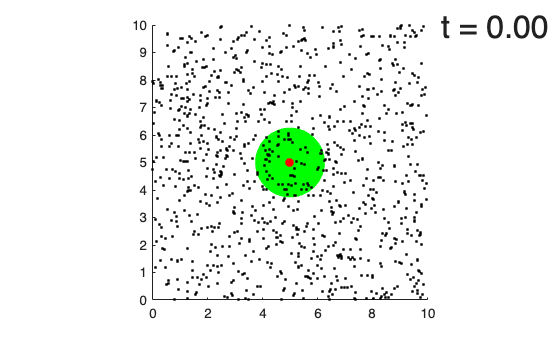

clear; clc;
n_ens = 8;
tf_long = 1500;     % long enough to see saturation

% Run WITH replenishment for comparison
[info, predator, prey] = lab4_default_params();
info.tf = tf_long;
[t1, m1, s1, ~] = lab4_ensemble(info, predator, prey, n_ens);

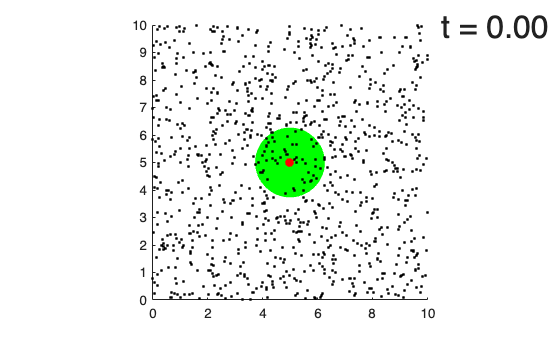

% Run WITHOUT replenishment
[info, predator, prey] = lab4_default_params();
info.tf             = tf_long;
info.replenish_prey = 0;
[t2, m2, s2, ~] = lab4_ensemble(info, predator, prey, n_ens);

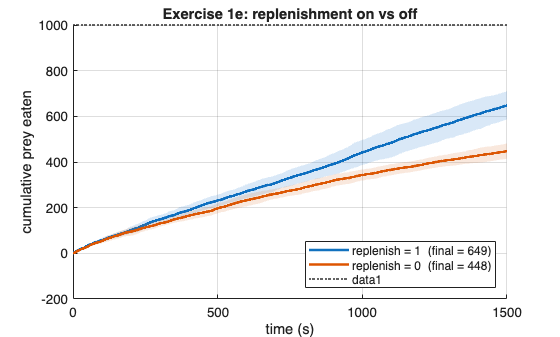

figure; hold on;
plot(t1, m1, 'LineWidth', 2, 'DisplayName', ...
     sprintf('replenish = 1  (final = %.0f)', m1(end)));
fill([t1 fliplr(t1)], [m1+s1 fliplr(m1-s1)], [0 0.4 0.8], ...
     'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
plot(t2, m2, 'LineWidth', 2, 'DisplayName', ...
     sprintf('replenish = 0  (final = %.0f)', m2(end)));
fill([t2 fliplr(t2)], [m2+s2 fliplr(m2-s2)], [0.85 0.4 0.1], ...
     'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
yline(prey.num, ':', 'total prey', 'LineWidth', 1.5);
xlabel('time (s)'); ylabel('cumulative prey eaten');
title('Exercise 1e: replenishment on vs off');
legend('Location', 'southeast'); grid on;

% Quantitative comparison: rate during early vs late windows
rate = @(t, m, t0, t1) ...
    (m(find(t >= t1, 1)) - m(find(t >= t0, 1))) / (t1 - t0);

fprintf('Replenish ON  - rate (prey/s): early = %.3f, late = %.3f\n', ...
        rate(t1, m1, 0, 100), rate(t1, m1, 1400, 1500));

Replenish ON  - rate (prey/s): early = 0.580, late = 0.385


fprintf('Replenish OFF - rate (prey/s): early = %.3f, late = %.3f\n', ...
        rate(t2, m2, 0, 100), rate(t2, m2, 1400, 1500));

Replenish OFF - rate (prey/s): early = 0.540, late = 0.195


## Exercise 2: 

## How does the total number of prey consumed compare to the prior case (original parameter except for handling time)? 

Adding a handling time of 0.5 reduced total prey consumed from 30.50 to 23.25 which is roughly a 24% decrease. Both curves remain linear over the 50 s simulation, but the handling time consistently slows the predator by forcing it to pause after each capture rather than immediately continuing to search.

Results from code below:

Th represents handling time 

`Th=0   : 30.00`

`Th=0.5 : 22.05`

## Can you set parameters such that predators are essentially handlingtime limited (hint: set detection and fraction consumed to be nearly 1 and also increase handling time)? 

Yes. Setting k = 1, f = 1, and Th = 2 pushes the predator into the handling-time-limited regime. By N = 10, the consumption rate has already plateaued at 0.482-0.483 prey and remains flat through N = 50 with nearly zero variance. The predator is spending almost all of its time processing captured prey rather than searching.

Results from code below:

`Handling-time-limited regime (k=1, f=1, Th=2.0):`

`N=  1 : rate = 0.171 +/- 0.030 prey/s   (1/Th = 0.50)`

`N=  2 : rate = 0.262 +/- 0.035 prey/s   (1/Th = 0.50)`

`N=  5 : rate = 0.426 +/- 0.029 prey/s   (1/Th = 0.50)`

`N= 10 : rate = 0.482 +/- 0.004 prey/s   (1/Th = 0.50)`

`N= 25 : rate = 0.483 +/- 0.000 prey/s   (1/Th = 0.50)`

`N= 50 : rate = 0.483 +/- 0.000 prey/s   (1/Th = 0.50)`

## In which case, does your model agree with predictions (see hypothesized consumption rate below)?

Yes, the model agrees with the prediction as stated in the section talking about hypothesized consumption rate. 

The Holling type II form predicts the consumption rate saturates at 1 / Th = 0.5 at high prey density and also that b / a = 1 / Th. It is 0.5 because the in my model Th is 2 seconds meaning a predator spends 2 seconds on each prey, so the maximum rate is 0.5 prey per second. The b / a = 1 / Th is given in the section below. 

The fitted curve gives b = 0.343, a = 0.686, and b/a = 0.500, matching the prediction exactly. The saturation is clearly visible in the plot, with the simulation points tracking the fitted curve closely and converging to the asymptote as early as N = 5 to 10.

Results from code below:

`Fit: b = 0.335, a = 0.669, b/a = 0.500  (predicted 1/Th = 0.500)`

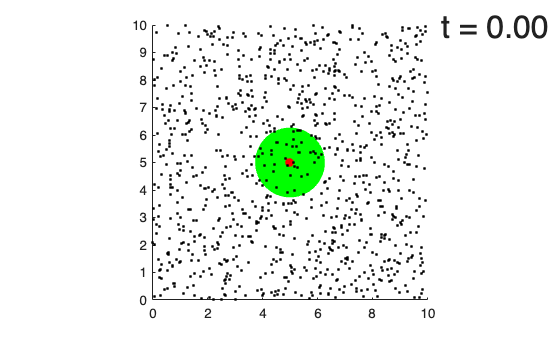

clear; clc;
n_ens = 20;

% default vs handling_time = 0.5
[info, predator, prey] = lab4_default_params();
[t_a, m_a, s_a, ~] = lab4_ensemble(info, predator, prey, n_ens);

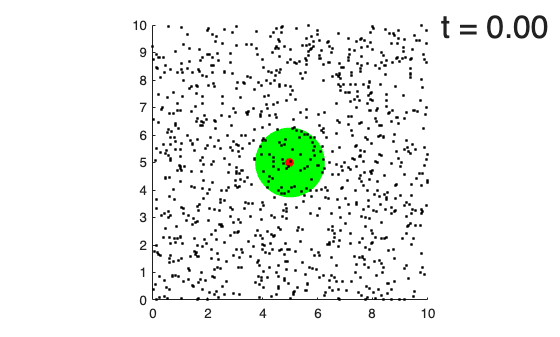

[info, predator, prey] = lab4_default_params();
predator.handling_time = 0.5;
[t_b, m_b, s_b, ~] = lab4_ensemble(info, predator, prey, n_ens);

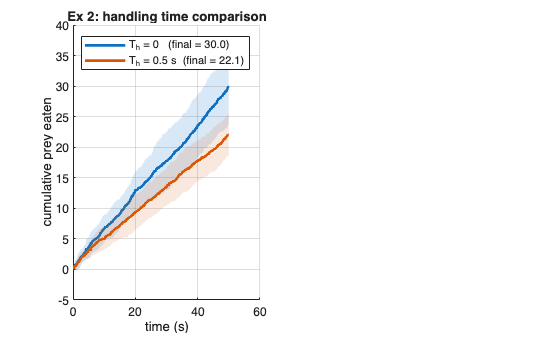

figure;
subplot(1,2,1); hold on;
plot(t_a, m_a, 'LineWidth', 2, 'DisplayName', sprintf('T_h = 0   (final = %.1f)', m_a(end)));
fill([t_a fliplr(t_a)], [m_a+s_a fliplr(m_a-s_a)], [0 0.4 0.8], ...
     'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
plot(t_b, m_b, 'LineWidth', 2, 'DisplayName', sprintf('T_h = 0.5 s  (final = %.1f)', m_b(end)));
fill([t_b fliplr(t_b)], [m_b+s_b fliplr(m_b-s_b)], [0.85 0.4 0.1], ...
     'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
xlabel('time (s)'); ylabel('cumulative prey eaten');
title('Ex 2: handling time comparison');
legend('Location', 'northwest'); grid on;

fprintf('Th=0   : %.2f\n', m_a(end));

Th=0   : 30.00


fprintf('Th=0.5 : %.2f\n', m_b(end));

Th=0.5 : 22.05


% vary density, k=f=1, Th=0.5 
densities = [1, 2, 5, 10, 25, 50];
Th        = 2;
rates     = zeros(size(densities));
rate_stds = zeros(size(densities));

fprintf('\nHandling-time-limited regime (k=1, f=1, Th=%.1f):\n', Th);


Handling-time-limited regime (k=1, f=1, Th=2.0):


  N=  1 : rate = 0.171 +/- 0.030 prey/s   (1/Th = 0.50)
  N=  2 : rate = 0.262 +/- 0.035 prey/s   (1/Th = 0.50)
  N=  5 : rate = 0.426 +/- 0.029 prey/s   (1/Th = 0.50)
  N= 10 : rate = 0.482 +/- 0.004 prey/s   (1/Th = 0.50)
  N= 25 : rate = 0.483 +/- 0.000 prey/s   (1/Th = 0.50)
  N= 50 : rate = 0.483 +/- 0.000 prey/s   (1/Th = 0.50)


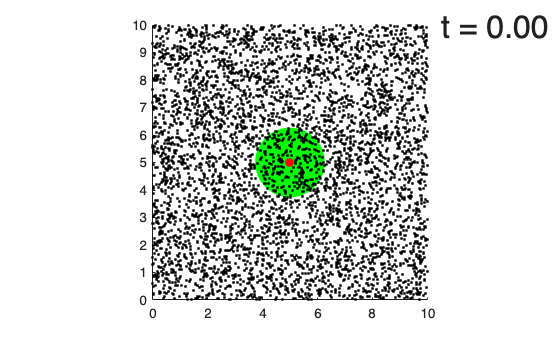

for i = 1:length(densities)
    [info, predator, prey] = lab4_default_params();
    info.prey_density       = densities(i);
    info.tf                 = 120;
    Th = 2;
    predator.handling_time  = Th;
    predator.k              = 1.0;
    predator.f              = 1.0;
    prey.num      = info.prey_density * info.maxX * info.maxY;
    prey.pos      = rand(prey.num, 2);
    prey.pos(:,1) = prey.pos(:,1) * info.maxX;
    prey.pos(:,2) = prey.pos(:,2) * info.maxY;

    n_ens_i = 10;     % heavier sims, fewer reps
    [t, m, s, ~] = lab4_ensemble(info, predator, prey, n_ens_i);
    rates(i)     = m(end) / t(end);
    rate_stds(i) = s(end) / t(end);
    fprintf('  N=%3d : rate = %.3f +/- %.3f prey/s   (1/Th = %.2f)\n', ...
            densities(i), rates(i), rate_stds(i), 1/Th);
end

% Fit Holling II with the constraint b/a = 1/Th
holling = @(p, N) p(1) * N ./ (1 + p(1)*Th .* N);  % b=p(1), a = b*Th
b_fit   = lsqcurvefit(holling, 0.5, densities, rates);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


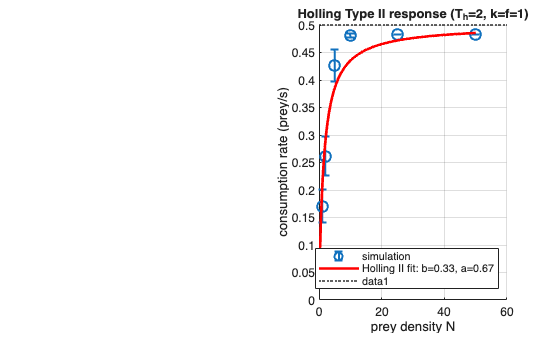

a_fit   = b_fit * Th;

subplot(1,2,2); hold on;
errorbar(densities, rates, rate_stds, 'o', 'MarkerSize', 8, 'LineWidth', 1.5, ...
         'DisplayName', 'simulation');
N_smooth = linspace(0.1, max(densities), 200);
plot(N_smooth, holling(b_fit, N_smooth), 'r-', 'LineWidth', 2, ...
     'DisplayName', sprintf('Holling II fit: b=%.2f, a=%.2f', b_fit, a_fit));
yline(1/Th, ':', sprintf('1/T_h = %.1f', 1/Th), 'LineWidth', 1.5);
xlabel('prey density N'); ylabel('consumption rate (prey/s)');
title('Holling Type II response (T_h=2, k=f=1)');
legend('Location', 'southeast'); grid on;

fprintf('\nFit: b = %.3f, a = %.3f, b/a = %.3f  (predicted 1/Th = %.3f)\n', ...
        b_fit, a_fit, b_fit/a_fit, 1/Th);


Fit: b = 0.335, a = 0.669, b/a = 0.500  (predicted 1/Th = 0.500)
